load("Learning\DS_DATA.mat")
padding = linspace(0,1000,45)'

padding = 1.0e+03 *

         0
    0.0227
    0.0455
    0.0682
    0.0909
    0.1136
    0.1364
    0.1591
    0.1818
    0.2045
    0.2273
    0.2500
    0.2727
    0.2955
    0.3182


[padding_size, ~] = size(padding)

padding_size = 45

tt = [padding; (C01_Discharge(:,3))./1000 + 1001];
u1 = [zeros(padding_size,1); 1.5 * 0.1 * ones(size(tt))];  
y  = [ones(padding_size,1).*C01_Discharge(1,2); C01_Discharge(:,2)];
[tt, ia] = unique(tt, 'stable');
y  = y(ia);
u1 = u1(ia);
[tt, sortIdx] = sort(tt);
y  = y(sortIdx);
u1 = u1(sortIdx);

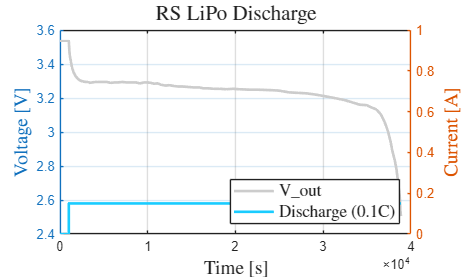

color_one = [0.8,0.8,0.8];
color_two = [0.1,0.8,1];
f_size = 14;

fig1 = figure; hold on
yyaxis left
plot(tt, y, 'color', color_one, 'linewidth', 2);
ylabel('Voltage [V]', 'interpreter', 'latex', 'fontsize', f_size);

yyaxis right
plot(tt, u1, 'color', color_two, 'linewidth', 2);
ylabel('Current [A]', 'interpreter', 'latex', 'fontsize', f_size);
ylim([0 1]);
xlabel('Time [s]', 'interpreter', 'latex', 'fontsize', f_size);
grid on
box on

leg = legend('V_{out}', 'Discharge (0.1C)', 'Location', 'southeast');
set(leg, 'interpreter', 'latex', 'fontsize', 13);
title('RS LiPo Discharge', 'interpreter', 'latex', 'fontsize', 16);
hold off